# Demo 4: segmentacja obrazu (segmentImage)

Skrypt odtwarza krok po kroku funkcję segmentImage: od klasyfikacji pikseli przez wygładzanie i morfologię do rozdzielenia stykających się obiektów transformatą wododziałową. Na końcu wynik jest porównywany z wywołaniem samej funkcji.

## Konfiguracja

W Live Editorze mfilename wskazuje na plik tymczasowy w /tmp, dlatego sprawdzamy kilka możliwych lokalizacji skryptu i wybieramy tę, dla której istnieje folder data/ dwa poziomy wyżej.

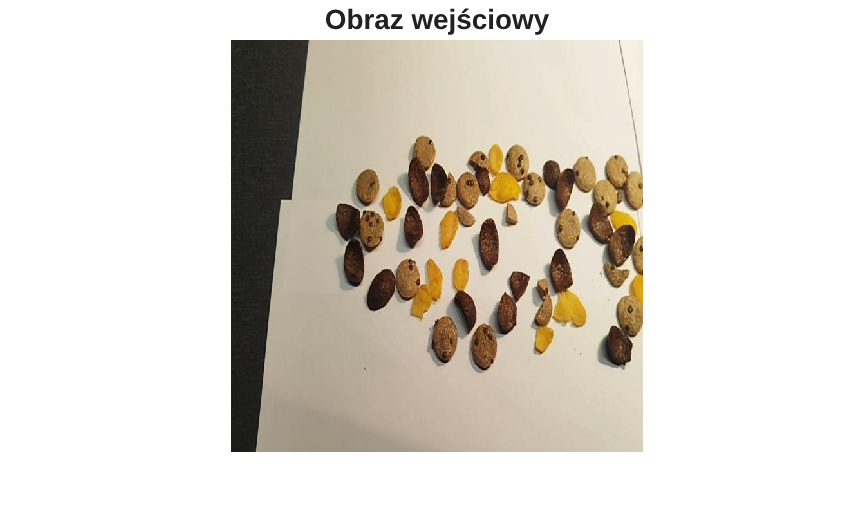

candidates = string(fileparts(mfilename("fullpath")));
try
    candidates(end+1) = fileparts(matlab.desktop.editor.getActiveFilename);
catch
end
candidates(end+1) = pwd;
candidates = candidates(candidates ~= "");
ok = arrayfun(@(d) isfolder(fullfile(d, "..", "..", "data")), candidates);
assert(any(ok), "Nie znaleziono folderu data/. Ustaw Current Folder na segmentation/demo.")
demoDir = candidates(find(ok, 1));
segDir  = fileparts(demoDir);
addpath(segDir);
dataDir = fullfile(segDir, "..", "data", "Mlekolaki.v3i.coco");

classNames = ["choco", "cookie", "corn"];
colors = [0.85 0.2 0.2; 0.2 0.5 0.95; 0.95 0.85 0.1];
cmap = [1 1 1; colors];                 % 0 = tło (białe)
showLabels = @(L) ind2rgb(double(L) + 1, cmap);

% Model koloru z main.m; jeśli go nie ma, uczymy go od nowa (ok. minuty).
lutFile = fullfile(segDir, "results", "colorLUT.mat");
if isfile(lutFile)
    load(lutFile, "lut");
else
    lut = trainPixelClassifier(loadCoco(fullfile(dataDir, "train")));
end

% Parametry takie jak domyślne w segmentImage.
minArea = 120; smoothSize = 5; hMin = 2;

f = dir(fullfile(dataDir, "test", "Video2_mp4-218_jpg*.jpg"));
I = imread(fullfile(f(1).folder, f(1).name));
figure; imshow(I); title("Obraz wejściowy")

## Krok 1: korekcja oświetlenia i klasyfikacja pikseli

Szczegóły korekcji: demo2_preprocess. Każdy piksel dostaje klasę z tablicy LUT na podstawie samego koloru.

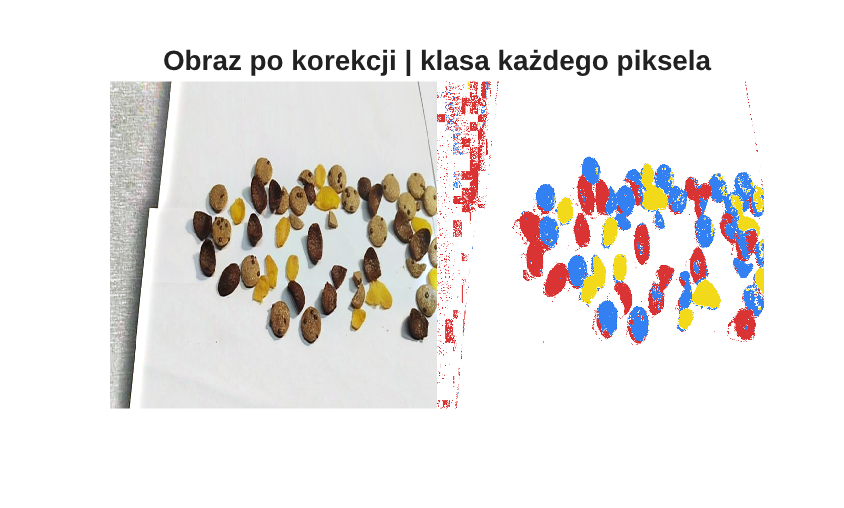

[J, roi] = preprocess(I);
bins = size(lut, 1);
q = idivide(uint16(J), uint16(256/bins)) + 1;
label0 = lut(sub2ind(size(lut), double(q(:,:,1)), double(q(:,:,2)), double(q(:,:,3))));
figure; montage({J, showLabels(label0)}, "Size", [1 2])
title("Obraz po korekcji | klasa każdego piksela")

## Krok 2: wygładzanie filtrem modalnym

Każdy piksel dostaje klasę najczęstszą w oknie 5x5. Usuwa to pojedyncze błędne piksele, np. kawałki czekolady na ciastkach oznaczone jako choco.

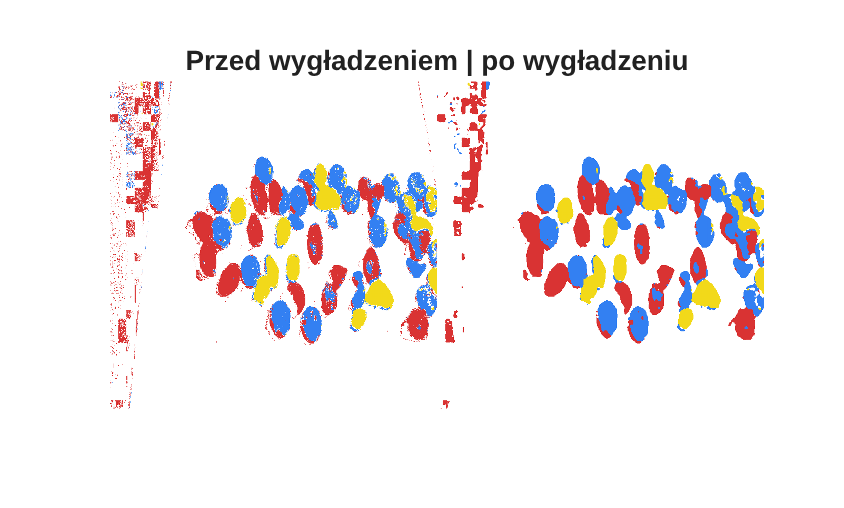

label1 = modefilt(label0, [smoothSize smoothSize]);
figure; montage({showLabels(label0), showLabels(label1)}, "Size", [1 2])
title("Przed wygładzeniem | po wygładzeniu")

## Krok 3: obcięcie do ROI

Wszystko poza papierem (ciemny materiał) staje się tłem.

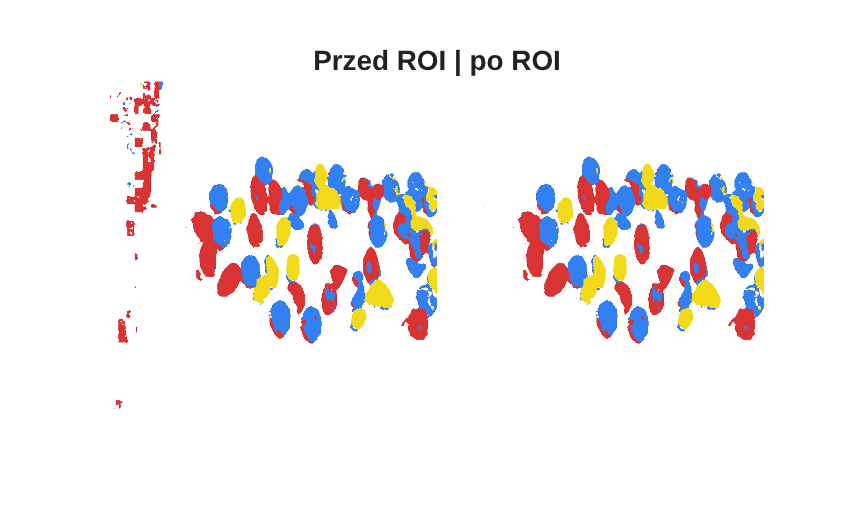

label2 = label1;
label2(~roi) = 0;
figure; montage({showLabels(label1), showLabels(label2)}, "Size", [1 2])
title("Przed ROI | po ROI")

## Krok 4: morfologia dla jednej klasy

Dalej każda klasa przetwarzana jest osobno. Tu pokazana jest klasa cookie (c = 2); można zmienić na 1 (choco) lub 3 (corn).

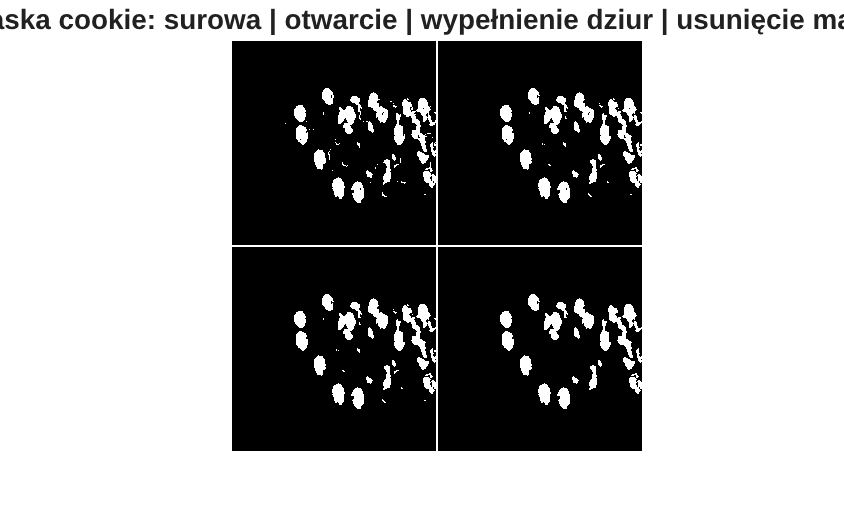

c = 2;
m0 = label2 == c;
m1 = imopen(m0, strel("disk", 2));       % usuwa cienkie wypustki i drobny szum
m2 = imfill(m1, "holes");                % wypełnia dziury (np. ciemne kawałki czekolady)
m3 = bwareaopen(m2, minArea);            % usuwa obiekty mniejsze niż minArea pikseli
figure
montage({m0, m1, m2, m3}, "Size", [2 2], "BorderSize", 4, "BackgroundColor", "w")
title("Maska " + classNames(c) + ": surowa | otwarcie | wypełnienie dziur | usunięcie małych")

## Krok 5: transformata odległościowa

Dla każdego piksela obiektu liczymy odległość do najbliższego tła. Środki obiektów mają największe wartości, a miejsca styku dwóch obiektów tworzą "przewężenia" o mniejszych wartościach.

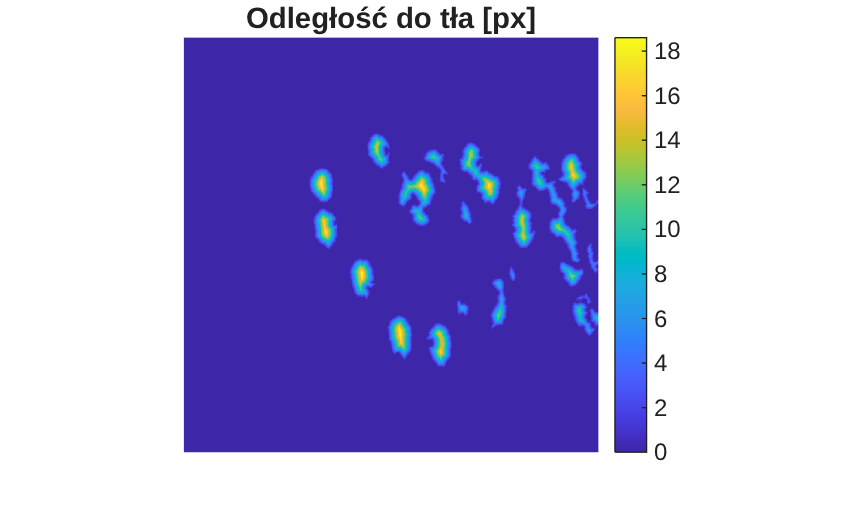

dist = bwdist(~m3);
figure; imshow(dist, []); colormap(gca, parula); colorbar
title("Odległość do tła [px]")

## Krok 6: znaczniki (markery) obiektów

imextendedmin znajduje lokalne minima ujemnej odległości (czyli środki obiektów) głębsze niż hMin. Każdy taki marker zostanie osobnym obiektem. Większe hMin daje mniej markerów i mniej podziałów.

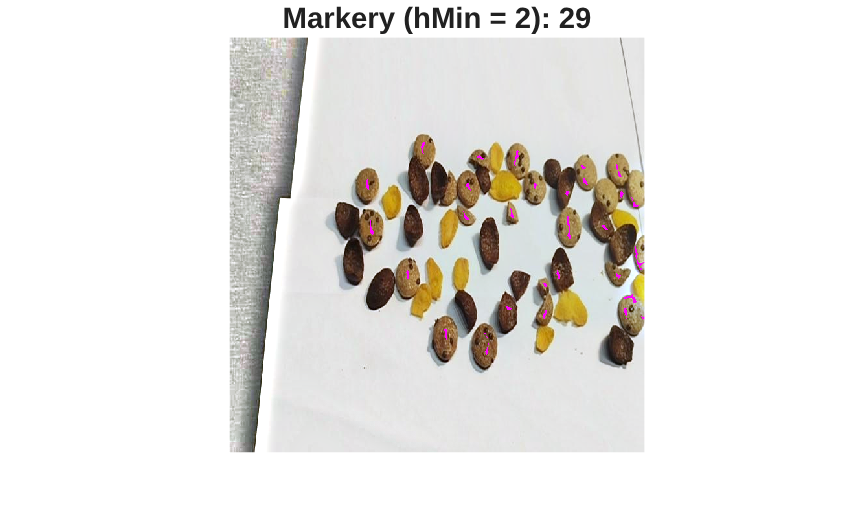

D = -dist;
markers = imextendedmin(D, hMin);
figure; imshow(labeloverlay(J, markers, "Colormap", [1 0 1], "Transparency", 0))
title(sprintf("Markery (hMin = %d): %d", hMin, bwconncomp(markers).NumObjects))

## Krok 7: transformata wododziałowa (watershed)

"Zalewamy" mapę od markerów. Gdzie spotykają się dwa zalewiska, powstaje linia podziału (W == 0), która rozcina stykające się obiekty.

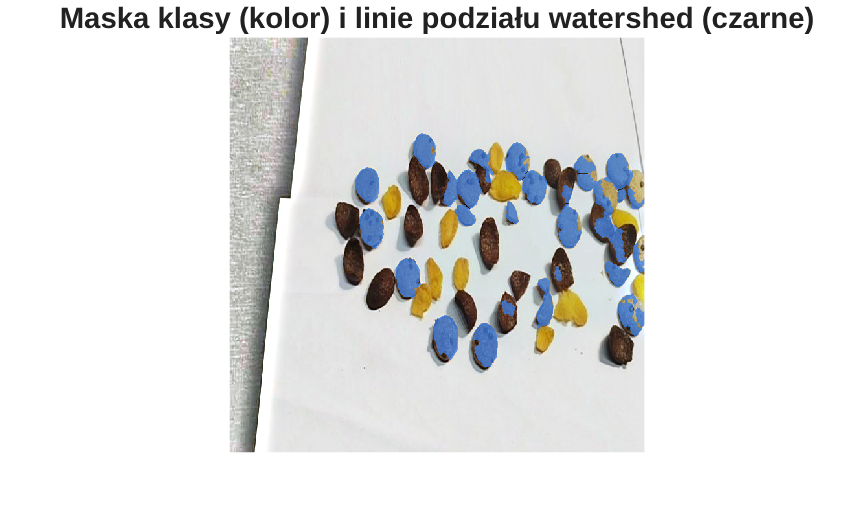

D2 = imimposemin(D, markers);
W = watershed(D2);
m4 = m3;
m4(W == 0) = false;
m5 = bwareaopen(m4, minArea);
lines = m3 & W == 0;
figure
imshow(labeloverlay(J, double(m3) + double(lines), "Colormap", [colors(c,:); 0 0 0], "Transparency", 0.3))
title("Maska klasy (kolor) i linie podziału watershed (czarne)")

Obiekty przed i po rozdzieleniu (każdy obiekt ma inny kolor).

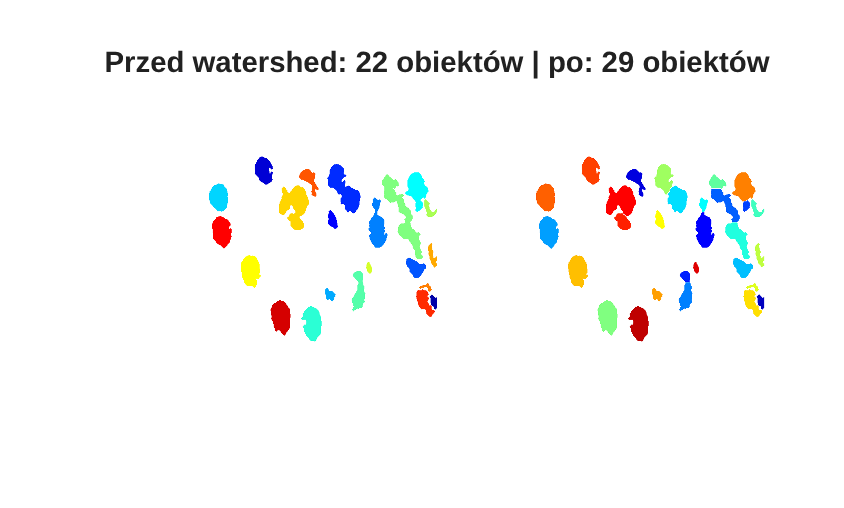

figure
montage({label2rgb(bwlabel(m3, 4), "jet", "w", "shuffle"), ...
         label2rgb(bwlabel(m5, 4), "jet", "w", "shuffle")}, "Size", [1 2])
title(sprintf("Przed watershed: %d obiektów | po: %d obiektów", ...
    bwconncomp(m3, 4).NumObjects, bwconncomp(m5, 4).NumObjects))

## Krok 8: wszystkie klasy razem

Ten sam proces (kroki 4-7) dla każdej klasy, zebrany w jedną mapę obiektów.

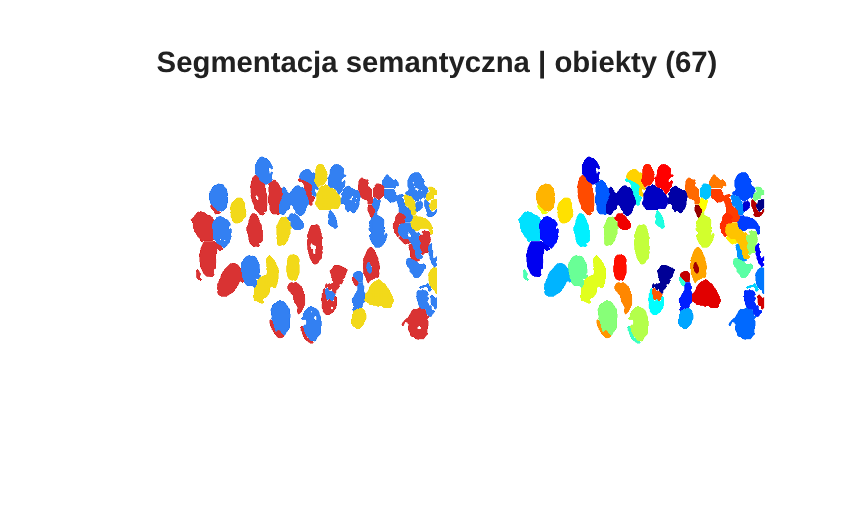

labelMap = label2;
instMap = zeros(size(labelMap));
inst = struct("label", {}, "bbox", {}, "area", {});
for c = 1:3
    m = labelMap == c;
    m = imopen(m, strel("disk", 2));
    m = imfill(m, "holes");
    m = bwareaopen(m, minArea);
    D = -bwdist(~m);
    D = imimposemin(D, imextendedmin(D, hMin));
    W = watershed(D);
    m(W == 0) = false;
    m = bwareaopen(m, minArea);
    cc = bwconncomp(m, 4);
    st = regionprops(cc, "BoundingBox", "Area");
    for k = 1:cc.NumObjects
        n = numel(inst) + 1;
        instMap(cc.PixelIdxList{k}) = n;
        inst(n).label = c;
        bb = st(k).BoundingBox;
        inst(n).bbox = [bb(1) - 0.5, bb(2) - 0.5, bb(3), bb(4)];
        inst(n).area = st(k).Area;
    end
    labelMap(labelMap == c & ~m) = 0;
end
figure
montage({showLabels(labelMap), label2rgb(instMap, "jet", "w", "shuffle")}, "Size", [1 2])
title(sprintf("Segmentacja semantyczna | obiekty (%d)", numel(inst)))

## Krok 9: wynik końcowy

Nakładka klas na obraz i ramki wyznaczone z obiektów.

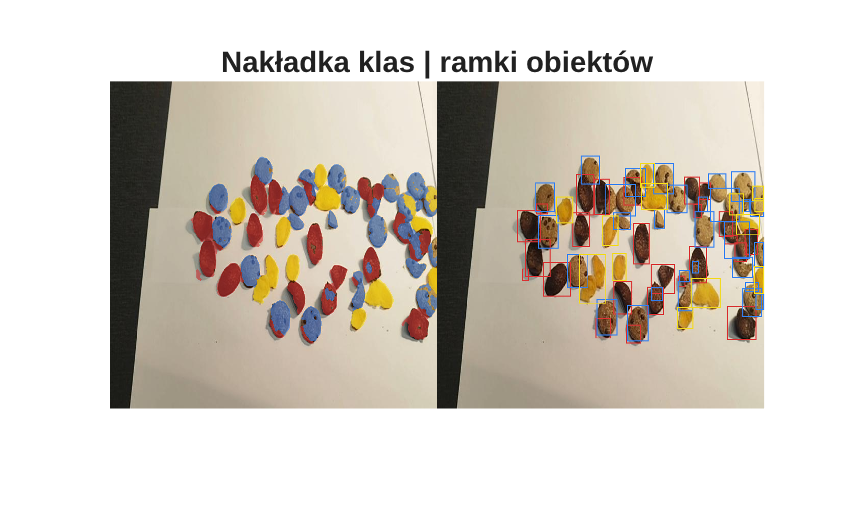

pb = reshape([inst.bbox], 4, []).';
pl = [inst.label].';
figure
montage({labeloverlay(I, labelMap, "Colormap", colors, "Transparency", 0.45), ...
         insertShape(I, "rectangle", pb, "Color", colors(pl, :) * 255, "LineWidth", 2)}, "Size", [1 2])
title("Nakładka klas | ramki obiektów")

counts = histcounts(pl, 0.5:3.5);
table(classNames.', counts.', 'VariableNames', ["klasa", "liczba"])

ans = 3×2 table
     klasa      liczba
    ________    ______

    "choco"       25  
    "cookie"      29  
    "corn"        13  


## Sprawdzenie: porównanie z funkcją segmentImage

[labelMap2, instMap2, inst2] = segmentImage(I, lut);
fprintf("labelMap identyczne: %d, instMap identyczne: %d, liczba obiektów: %d vs %d\n", ...
    isequal(labelMap, labelMap2), isequal(instMap, instMap2), numel(inst), numel(inst2));

labelMap identyczne: 1, instMap identyczne: 1, liczba obiektów: 67 vs 67
